## -------------------------------------------------------------------------------

## ZAD 1 ----------------------------------------------------------------------

## -------------------------------------------------------------------------------

## Układ mechaniczny

y'' + by' + cy + dy^3 = 0

#### Krok 1

clear all;
close all;
warning('off', 'all')

syms b c d
b_d = 0.5;
c_d = 0.6;
d_d = (-0.7);
x = sym('x',[1 2])

$$x = \left(\begin{array}{cc} x_{1} & x_{2} \end{array}\right)$$


%Krok 1

mech_syms = [x(2);
             -b*x(2) - c*x(1) - d*(x(1).^3)]

$$mech\_syms = \left(\begin{array}{c} x_{2}\\ -d\,{x_{1}}^{3}-c\,x_{1}-b\,x_{2} \end{array}\right)$$


mech_syms_fun_wrap = matlabFunction(subs(mech_syms, [b c d], [b_d c_d d_d]))

mech_syms_fun_wrap = function_handle with value:
    @(x1,x2)[x2;x1.*(-3.0./5.0)-x2./2.0+x1.^3.*(7.0./1.0e+1)]



mech_syms_jac = jacobian(mech_syms, x)

$$mech\_syms\_jac = \left(\begin{array}{cc} 0 & 1\\ -3\,d\,{x_{1}}^{2}-c & -b \end{array}\right)$$


assume(d, 'positive');
Sx_dpos = solve(mech_syms);
[Sx_dpos.x1, Sx_dpos.x2];

#### Krok 2

mech_sym_jac_eq = [];
mech_sym_jak_eq_eig = [];
for n = 1:3
    jac_eq = subs(mech_syms_jac, [x(1), x(2)], [Sx_dpos.x1(n), Sx_dpos.x2(n)]);
    mech_syms_jac_eq(:, :, n) = jac_eq;
    [D, V]  = eig(jac_eq);
end
mech_syms_jac_eq;

#### Krok 3-4

xlim = [-5, 5];
ylim = [-5, 5];
sens = 0.1;
tspan = linspace(0, 10, 100);

x1_eq = subs(Sx_dpos.x1, [b, c, d], [b_d, c_d, d_d])

$$x1\_eq = \left(\begin{array}{c} 0\\ \frac{\sqrt{3}\,\sqrt{5}\,\sqrt{7}\,\sqrt{10}}{35}\\ -\frac{\sqrt{3}\,\sqrt{5}\,\sqrt{7}\,\sqrt{10}}{35} \end{array}\right)$$

x2_eq = subs(Sx_dpos.x2, [b, c, d], [b_d, c_d, d_d])

$$x2\_eq = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

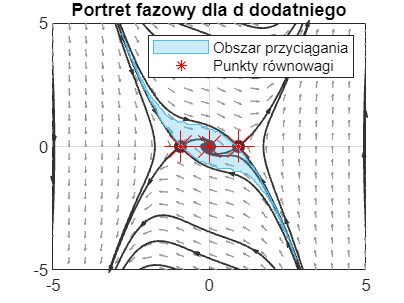


odefun = @(t, x) mech_syms_fun_wrap(x(1), x(2));
plotpp(odefun, xlim = xlim, ylim = ylim)
hold on
x_ = [];
y_ = [];

for x_1 = xlim(1):sens:xlim(2)
    for x_2 = ylim(1):sens:ylim(2)
        [t,y] = ode23 (@(t, x) mech_syms_fun_wrap(x(1), x(2)), tspan, [x_1 x_2] );
        for n = 1:numel(x1_eq)
            if abs(y(end,1) - x1_eq(n)) < sens &&...
                    abs(y(end, 2) - x2_eq(n)) < sens 
                x_(end + 1) = x_1;
                y_(end + 1)= x_2;
            end %if
        end %for
    end %for
end %for

arg = [];
first = [];
second = [];
for x_1 = x_
    arg(end + 1) = x_1;
    index = find(x_ == x_1);
    values = y_(index);
    first(end + 1) = min(values);
    second(end + 1) = max(values);
end

x_ = [arg,sort(arg, 'descend')];
y_ = [first, flip(second)];
p = fill (x_ ,y_ ,[0.3010 0.7450 0.9330],'FaceAlpha',0.3);
p.EdgeColor = [0.3010 0.7450 0.9330];
plot(0, 0, '.', 'Color', 'red')
sc = scatter(x1_eq, x2_eq, 300 ,"r*");
legend([p, sc], ["Obszar przyciągania", "Punkty równowagi"]);
title("Portret fazowy dla d dodatniego")
hold off

#### Krok 5

x1_eq = 0

x2_eq = 0

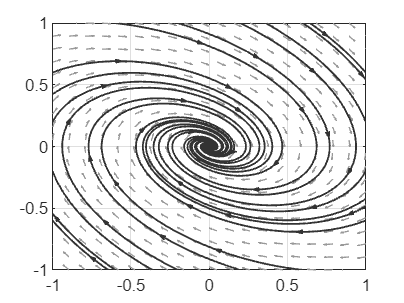

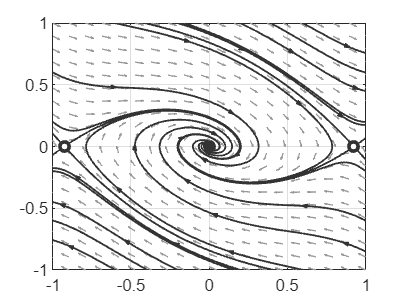

x1_eq = 0.9258

x2_eq = 0

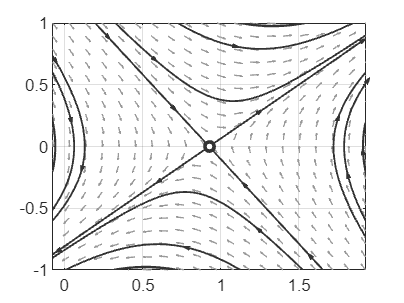

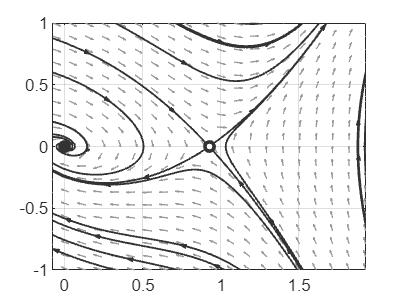

x1_eq = -0.9258

x2_eq = 0

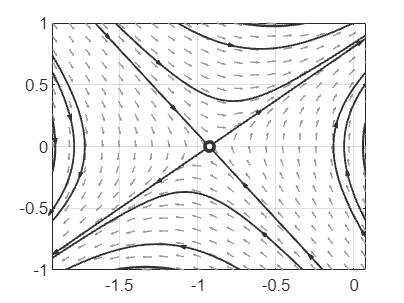

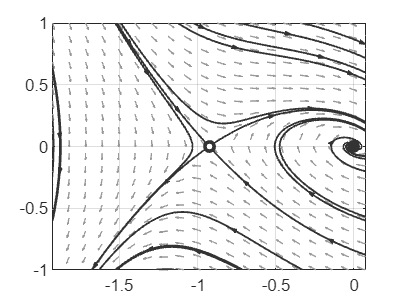

%plotpp(@(t, x) mech_syms_fun_wrap(x(1), x(2))); % plot the phase portraits
%hold on;

lin_approx_vec = [];

for n = 1:3
    x1_eq = double(subs(Sx_dpos.x1(n), [b c d], [b_d c_d d_d]))
    lin_approx = zeros([2, 2]);
    x2_eq = double(subs(Sx_dpos.x2(n), [b c d], [b_d c_d d_d]))
    x1lim = [x1_eq-1, x1_eq+1];
    x2lim = [x2_eq-1, x2_eq+1];

    if(isreal(x1_eq) && isreal(x2_eq))
    
        lin_approx = double(subs(mech_syms_jac_eq, [b, c, d], [b_d, c_d, d_d]));
        lin_approx = lin_approx(:, :, n);
        lin_approx_vec(:, :, n) = lin_approx;
        
        plotpp(@(t, x) lin_approx * ([x(1); x(2)] - [x1_eq; x2_eq]), xlim = x1lim, ylim = x2lim)
    
        plotpp(@(t, x) mech_syms_fun_wrap(x(1), x(2)), xlim = x1lim, ylim = x2lim);
    
    end %if
end

#### Krok 6

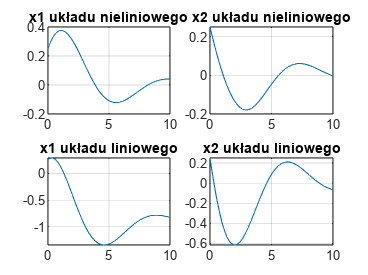

x0 = [0.25; 0.25];
[ t , x ] = ode45 (@( t , x)  mech_syms_fun_wrap(x(1), x(2)) , [0  10] , x0);
[ t_lin , x_lin ] = ode45 (@( t , x)  lin_approx_vec(:,:, 1) * ([x(1); x(2)] - [x1_eq; x2_eq]) , [ 0  10] , x0);

figure
subplot(2, 2, 1)
plot(t, x(:, 1));
title(["x1 układu nieliniowego"])
grid on;
subplot(2, 2, 2)
plot(t, x(:, 2))
title(["x2 układu nieliniowego"])
grid on;
subplot(2, 2, 3)
plot(t_lin, x_lin(:, 1));
title(["x1 układu liniowego"])
grid on;
subplot(2, 2, 4)
plot(t_lin, x_lin(:, 2))
title(["x2 układu liniowego"])
grid on;
filename = sprintf("mech_zmienne_stanu_x0%d.png", x0);
saveas(gcf, filename);

## -------------------------------------------------------------------------------

## ZAD 2 ----------------------------------------------------------------------

## -------------------------------------------------------------------------------

syms c l m
b_d = 0.5;
c_d = 0.6;
d_d = (-0.7);
x = sym('x',[1 2])

system38_sym = [x(2);
    -9.81/l * sin(x(1)) - c/(l*m) * x(2)]

